## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

% For different number of total vehicles, we may need to change the lower
% bound of the con0 in vehicle class for decentralization (0.001/0.0001)
% 0.007 0.005 0.004
rng(7)
% addpath(genpath('/home/shirantha27/mosek/10.2/toolbox/r2017aom'))
% addpath(genpath('/home/shirantha27/mosek/YALMIP-master'))


Creation of the network of platoons

%% Setup
network_index = 0;                     % network Index
numOfPlatoons = 1;                     % num of platoons
numOfVehicles = [7]; %[4,5,6,7,8,10];    % num of vehicles in each platoon, for N=8, 10, the lower bound of the con0 is set as 0.001
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 10;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - (vehicleSeperationMean+length_ki) - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + (vehicleSeperationMean+length_ki);

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        % noisemean_ki = rand(3,1);
        % noisestd_ki = 0.1*rand(3,1);

        noisemean_ki = zeros(3,1);
        % rand(3,1)-0.5*ones(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

% Platoon simulation video figure setup
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)

#### Synthesizing controllers for the platoon

**Configuration 1:** Centralized Stabilizing Control using Error Dynamics II

Note: Local passivating controller synthesis should not use a cost function in order to get a set of local controller gain coefficients that are smaller (and thus, practical).

% %%% Global controller synthesis specifications
% % Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
% errorDynamicsType = 2;  % Error dynamics formulation I or I
% isCentralized = 1;      % Centralized or decentralized controller synthesis
% isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)
% gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar  % Desired max noise attenuation
% 
% %%% Local passivating controller synthesis specifications 
% % LowerBound on \nu and upperBound on \rho 
% nuBar = -10;        % For the constraint: nu >= nuBar       %nuBar = -8.1
% rhoBar = 5;         % For the constraint: rho <= rhoBar     %rhoBar = 4.1

**Configuration 2:** Centralized Robust Control using Error Dynamics II

Note: In the local passivating controller synthesis, when no cost function is used, the resulting passivity indices are not amenable to global controller synthesis. 

To resolve this, we can resort to using the fundamental cost function for local passicating controller synthesis. However, this leads to: (Issue 1) larger local controller gains, and (Issue 2) global controller gains with no inter-vehicle interconnections. 

To solve the first issue, we can resort to use a cost function (in local passivating controller synthesis) of the form: 0.0000001*(- nu + rhoBar); This leads to relatively low local controller gains as well as passivity indices that are amenable to global controller synthesis. However, (Issue 2) is still a problem. 

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation I or I
isCentralized = 0;      % Centralized or decentralized controller synthesis
isDSS = 0;               % Involve DSS constraints (1) or not (0)
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
pVals = net.optimizeCodesignParameters(isCentralized,isDSS)

Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
Global Synthesis Failed
Decentralized Synthesis Success at: 1 with gammaSq=3.044.


Decentralized Synthesis Failed at: 2.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    9.800000e+05    0.000e+00    0.000e+00

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

pVals =     0.1667
    0.1667
    0.1667
    0.1667
    0.1667
    0.1667


fval = 980000

pVals =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667


% pVals = [0.1111 0.1111]
%% Resulting optimal parameters for Centralized case
% pVals = [0.0053    0.0451    0.0444    0.0453    0.0450] % after all tweaks (centralized)
%% Resulting optimal parameters for Decentralized case
% pVals = [0.1995    0.1282    0.2070    0.1636    0.2022] % after all tweaks (centralized)

%% An alternative: Trying some fixed set of parameters.
% pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));
%% Some other alternatives:
% pVals = [0.0203    0.0203    0.0202    0.0202    0.0204] % with initial condition 0.15
% pVals = [0.0029    0.0029    0.0028    0.0029    0.0029] % with initial condition 0.1


%%% Execution of the controller synthesis
%net.platoons(1).vehicles(2).synthesizeLocalControllers(2,nuBar,rhoBar)
% Actually, above defined nuBar,rhoBar,gammaSqBar are no longer needed

tic
net.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

Robust Stabilizing at: 1 after .
Local Synthesis Success at: 1 with gammaSq=2.925.
Data saved at: 1.
LMI is feasible at: 1, thus continued.
Decentralized Synthesis Success at: 1 with gammaSq=3.044.
Elapsed time is 0.120521 seconds.
Current K at i = 1
   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0284

Robust Stabilizing at: 2 after 1.
Local Synthesis Success at: 2 with gammaSq=2.925.
Data saved at: 2 after 1.
LMI is feasible at: 2 after 1.
Decentralized Synthesis Success at: 2 with gammaSq=3.044.
Elapsed time is 0.328900 seconds.
 Local controller updated at j = 1
Current K at i = 2
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0284   -0.0000   -0.0000    0.0001
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0001    0.0000    0.0000   -0.0284

R

obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 7
         vehicles: [1×7 Vehicle]
         topology: [1×1 Topology]
        graphics1: [45.1918 47.1918 49.1918 51.1918 53.1918 55.1918 57.1918 59.1918 61.1918 63.1918 65.1918 67.1918 69.1918 71.1918 73.1918]
        graphics2: [46.1918 48.1918 50.1918 52.1918 54.1918 56.1918 58.1918 60.1918 62.1918 64.1918 66.1918 68.1918 70.1918 72.1918 74.1918]
                K: {6×6 cell}
                R: []
        KSequence: {{1×1 cell}  {2×2 cell}  {3×3 cell}  {4×4 cell}  {5×5 cell}  {6×6 cell}}


Synthesis Success at Platoon 1.


toc

Elapsed time is 0.211550 seconds.



%%% To check compositionality, lets see K_{13} value at decentralized iteration = 3,4,5 and 6
% format long
net.platoons(1).KSequence{3}{1,3}

ans =   -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000
   0.002672021337310   0.002672011242425   0.002720987733633


net.platoons(1).KSequence{4}{1,3}

ans =   -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000
   0.002672021337310   0.002672011242425   0.002720987733633


net.platoons(1).KSequence{5}{1,3}

ans =   -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000
   0.002672021337310   0.002672011242425   0.002720987733633


net.platoons(1).KSequence{6}{1,3}

ans =   -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000
   0.002672021337310   0.002672011242425   0.002720987733633


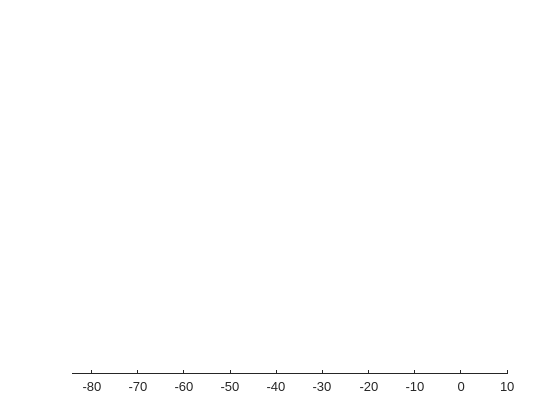

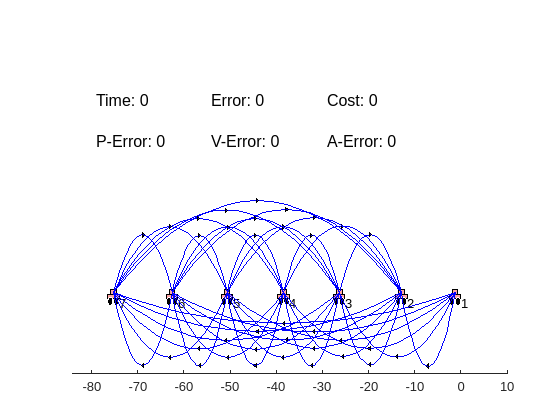




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compute the cost \sum_{i=1}^N cij*|K_ij|+c0*gamma

%Then we use hard constraint

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%% In decentralized implementation, there are two things to consider:
% gammaSq_i needs to be costrainted at each subsystem i (or penalized considerably), 
% otherwise it tends to grow with i. Recall that max(gammaSq_i) = gammaSq. 
% There is a zero eigenvalue in the main LMI constraint (this is also in the
% centralized problem). This may be the reason why solver gives "Unknown Status" error.

%%% Graphing the Resulting topology
figure(2)
hold on
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(2)

Executing the k_j0 updates based on K_ji values - done

Two things to do next: 

Printing intermediate platoons in the decentralized design and verify the compositionality

Avoid controller gain filtering by including a threshold in the local LMI problems

optimizing pvals

Running the Simulation - Updating the states

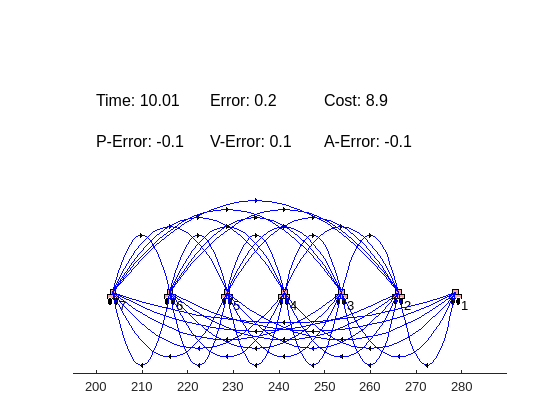

% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;
timeLength = length(tArray);

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(2)
    pause(0.01)

end

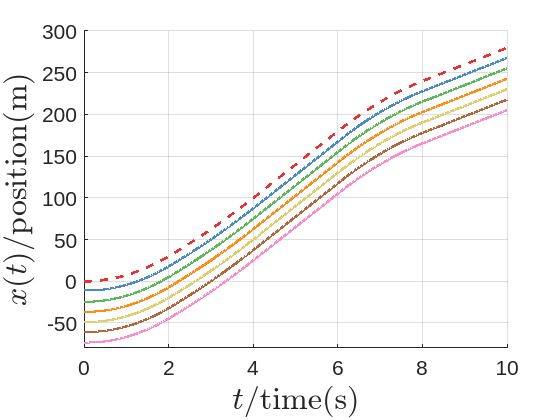

% Plot the state histories
C = linspecer(numOfVehicles(1));


figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,net.platoons(k).vehicles(1).stateHistory(1,:)','--',LineWidth=2);
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$x(t)$/position(m)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-80 300]);
grid on 

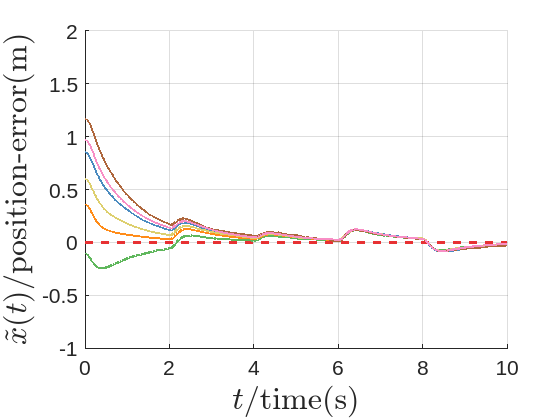



% Plot the location error histories
figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2);
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$\tilde{x}(t)$/position-error(m)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-1 2]);
grid on 

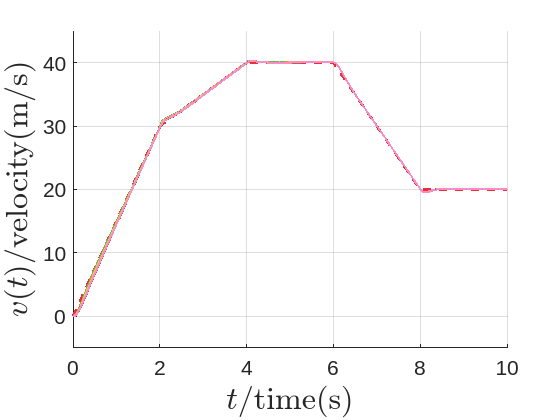



figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,net.platoons(k).vehicles(1).stateHistory(2,:)','--',LineWidth=2);
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$v(t)$/velocity(m/s)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-5 45]);
grid on 

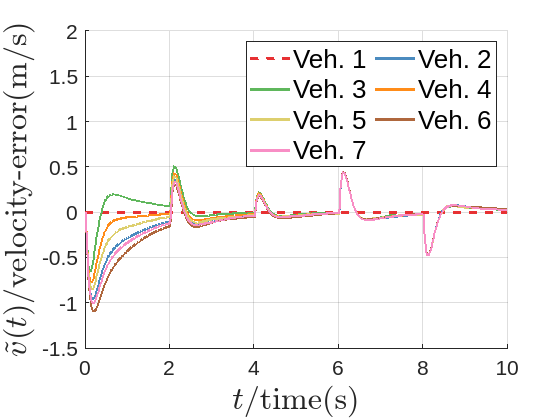




figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Veh. ',num2str(1)]);
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex',fontsize=24)
legend(Location="northeast",FontSize=20,NumColumns=2,Orientation="horizontal")
xlim([0 10]);
ylim([-1.5 2]);
grid on 

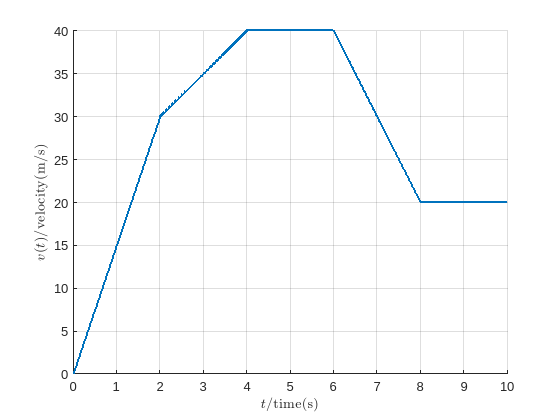



% % Plot the state histories of leaders
% figure
% hold on
% for k = 1:1:numOfPlatoons
%     for i = 1
%         plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
%     end
% end
% xlabel('$t$/time(s)','Interpreter','latex')
% ylabel('$x(t)$/position(m)','Interpreter','latex')
% % legend(Location="eastoutside")
% grid on 
% 
% 
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/velocity(m/s)','Interpreter','latex')
% legend(Location="eastoutside")
grid on 

Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation